# Proyecto PRIME

clear; close all; format compact

## 1. Implementación de todos los modos de comunicación de PRIME en el caso de canal sin distorsión y sin FEC (4pts)

#### 1. Elección de parámetros de simulación

    El número de símbolos OFDM por trama se establece para que el canal en caso de ser dispersivo sea estable durante 100 ms. En la página 13 de la ITU-T G.9904 se especifica que la duración del payload para M símbolos OFDM debe ser M*2.24ms. La duración de un símbolo OFDM debe ser 2.24ms. 

    * *Asumimos que el tiempo de estabilidad de 100ms se aplica a la trama completa (preamble+header+payload)*

% T_pre = 2.048 % Duracion del preamble (ms)
tSym = 2.24; % Durancion de un símbolo OFDM (ms)
tTotal = 100; % Duración de una trama OFDM (ms)
Nofdm = floor((tTotal)/tSym); % Número de símbolos OFDM por trama

    En la página 16 de la ITU-T G.9904 indica que se deben usar 96 portadoras de datos

nPay = 96; % Número de tramas payload

    El número de bits se establece para obtener valores de BER fiables, inferiores incluso a 10-4.

mcm = log2(2)*log2(4)*log2(8); % MCM
nBits = nPay*Nofdm*mcm; % Número de bits

#### 2. Mostrar que el comportamiento del sistema simulado corresponde con el teórico en términos de curvas de BER frente a SNR, para todos los modos de comunicación sin FEC definidos en el estándar. SNR es la relación señal a ruido a la entrada del receptor sobre el ancho de banda útil de la señal OFDM, las frecuencias para las que las portadoras no son nulas, para un canal AWGN invariante en frecuencia, es decir, considerando que la respuesta impulsiva de canal es h[n] = [1]. 

Mostrar que, en ausencia de ruido, y sin incluir prefijo cíclico, la transmisión recepción, empleando en la cadena de transmisión únicamente modulador DPSK + IFFT, y en la de recepción FFT + demodulador DPSK, no genera ningún error. 

% Vector de bits a transmitir
txBits = round(rand(1,nBits));

El tamaño de la NFFT es de 512 muestras.

% Variables
NFFT = 512;

Se realiza la IFFT de las señales moduladas.

% Modulación DNPSK de los bits aleatorizados
x.dbpsk = modDNPSK(txBits,2,NFFT,Nofdm);
x.dqpsk = modDNPSK(txBits,4,NFFT,Nofdm);
x.d8psk = modDNPSK(txBits,8,NFFT,Nofdm);

% Demodulación DNPSK
rxBits.dbpsk = demodDNPSK(x.dbpsk,2,NFFT,Nofdm);
rxBits.dqpsk = demodDNPSK(x.dqpsk,4,NFFT,Nofdm);
rxBits.d8psk = demodDNPSK(x.d8psk,8,NFFT,Nofdm);

Mostrar la ausencia de errores de transmisión cuando se añade a la cadena del punto anterior los bloques de aleatorización y desaleatorización. 

% Error en la transmisión DBPSK
error.dbpsk = sum(rxBits.dbpsk-txBits);
disp("El error de transmisión en DBPSK es: " + error.dbpsk)

El error de transmisión en DBPSK es: 0


% Error en la transmisión DQPSK
error.dqpsk = sum(rxBits.dqpsk-txBits);
disp("El error de transmisión en DQPSK es: " + error.dqpsk)

El error de transmisión en DQPSK es: 0


% Error en la transmisión D8PSK
error.d8psk = sum(rxBits.d8psk-txBits);
disp("El error de transmisión en D8PSK es: " + error.d8psk)

El error de transmisión en D8PSK es: 0


#### **3. Mostrar la ausencia de errores de transmisión cuando se añade a la cadena del punto anterior los bloques de aleatorización y desaleatorización. **

Aleatorización de la secuencia de bits.

% Aleatorización
randomizedBits = scrambler(txBits);

Modulación y Demodulación. 

% Modulación DNPSK de los bits aleatorizados
x.dbpsk = modDNPSK(randomizedBits,2,NFFT,Nofdm);
x.dqpsk = modDNPSK(randomizedBits,4,NFFT,Nofdm);
x.d8psk = modDNPSK(randomizedBits,8,NFFT,Nofdm);

% Demodulación DNPSK
rxBits.dbpsk = demodDNPSK(x.dbpsk,2,NFFT,Nofdm);
rxBits.dqpsk = demodDNPSK(x.dqpsk,4,NFFT,Nofdm);
rxBits.d8psk = demodDNPSK(x.d8psk,8,NFFT,Nofdm);

Desaleatorización.

% Aleatorización DBPSK
unrandomizedBits.dbpsk = scrambler(rxBits.dbpsk);
% Aleatorización DQPSK
unrandomizedBits.dqpsk = scrambler(rxBits.dqpsk);
% Aleatorización D8PSK
unrandomizedBits.d8psk = scrambler(rxBits.d8psk);

Se comprueba cuantos bits han resultado erróneos.

% Error en la transmisión DBPSK aleatorizada
error.dbpsk = sum(abs(unrandomizedBits.dbpsk-txBits));
disp("El error de transmisión en DBPSK es: " + error.dbpsk)

El error de transmisión en DBPSK es: 0


% Error en la transmisión DQPSK aleatorizada
error.dqpsk = sum(abs(unrandomizedBits.dqpsk-txBits));
disp("El error de transmisión en DQPSK es: " + error.dqpsk)

El error de transmisión en DQPSK es: 0


% Error en la transmisión D8PSK aleatorizada
error.d8psk = sum(abs(unrandomizedBits.d8psk-txBits));
disp("El error de transmisión en D8PSK es: " + error.d8psk)

El error de transmisión en D8PSK es: 0


Finalmente, representar las curvas BER vs SNR teóricas y simuladas, estas últimas empleando secuencias de bits seudoaleatorias. 

% Vector SNR 
SNR_dB = 0:2:20;

La BER teórica:

% Cálculo de la BER teórica DBPSK, DQPSK y D8PSK
BER.teo.dbpsk = DBPSK_BER(SNR_dB);
BER.teo.dqpsk = DQPSK_BER(SNR_dB);
BER.teo.d8psk = D8PSK_BER(SNR_dB);

BER.teo.dbpsk(find(BER.teo.dbpsk<1e-5)) = NaN;
BER.teo.dqpsk(find(BER.teo.dqpsk<1e-5)) = NaN;
BER.teo.d8psk(find(BER.teo.d8psk<1e-5)) = NaN;

La BER simulada:

% Cáculo de la BER simulada DBPSK, DQPSK y D8PSK
BER.sim.dbpsk = simulateDNPSK_BER(SNR_dB,2,NFFT,Nofdm,nPay,nBits);
BER.sim.dqpsk = simulateDNPSK_BER(SNR_dB,4,NFFT,Nofdm,nPay,nBits);
BER.sim.d8psk = simulateDNPSK_BER(SNR_dB,8,NFFT,Nofdm,nPay,nBits);

Representación de las curvas de BER

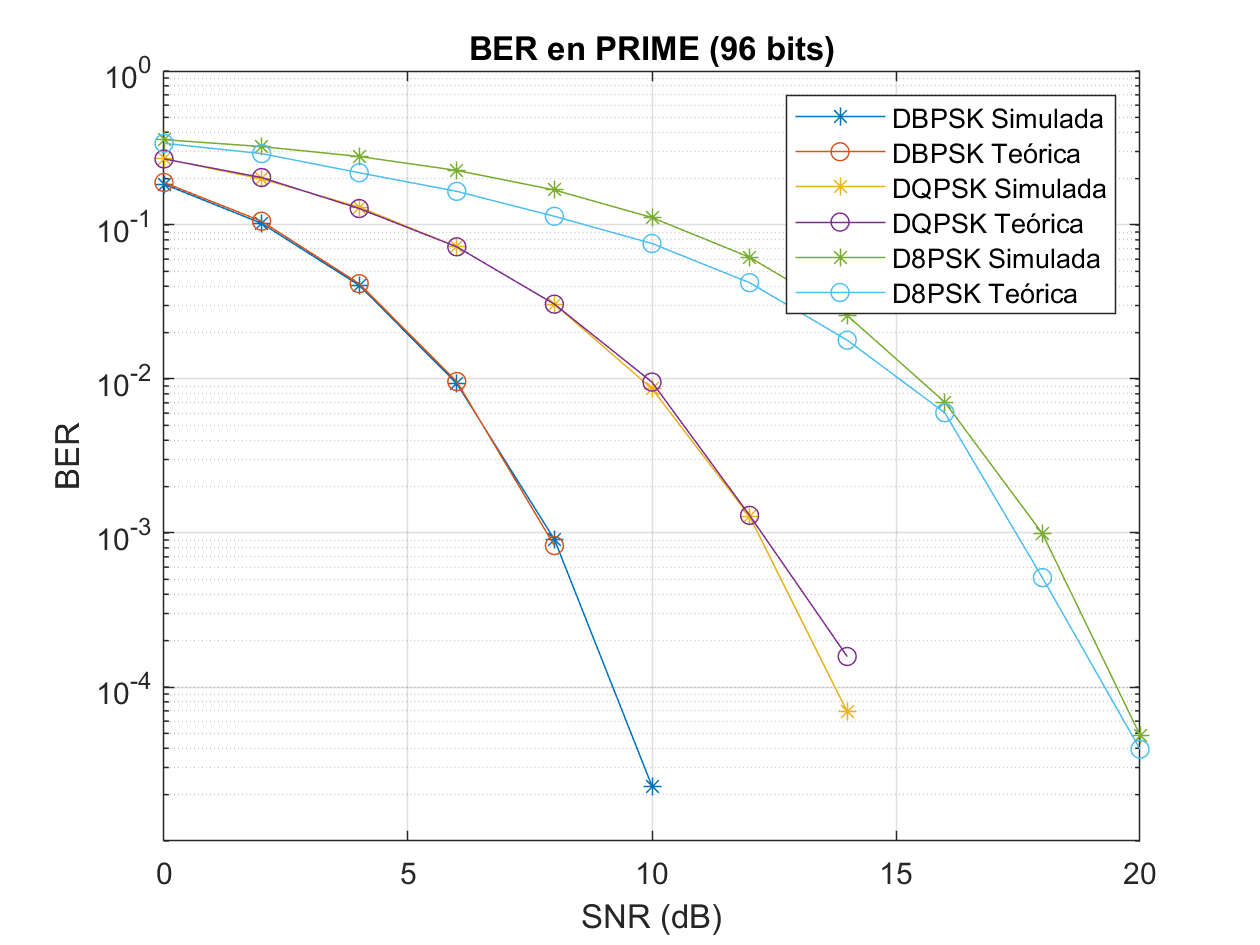

figure;
semilogy(SNR_dB, BER.teo.dbpsk, '-*');   
hold on;
semilogy(SNR_dB, BER.sim.dbpsk, '-o');
grid on;
semilogy(SNR_dB, BER.teo.dqpsk, '-*');
semilogy(SNR_dB, BER.sim.dqpsk, '-o');
semilogy(SNR_dB, BER.teo.d8psk, '-*');
semilogy(SNR_dB, BER.sim.d8psk, '-o');
xlim([SNR_dB(1) SNR_dB(end)]);
ylim([1e-5 1]);
legend('DBPSK Simulada','DBPSK Teórica','DQPSK Simulada','DQPSK Teórica','D8PSK Simulada','D8PSK Teórica')
xlabel('SNR (dB)'); 
ylabel('BER');
title(['BER en PRIME (' num2str(round(nPay,1)) ' bits)']);

##  2. Inclusiónde modelo de canal e inclusión de ecualizador (3 puntos). 

Para este apartado, se incluye un canal invariante en frecuencia. Se asume que el canal posee la siguiente repuesta al impulso discreto.

% Definicion del canal h[n]
h = [-0.1, 0.3, -0.5, 0.7, -0.9, 0.7, -0.5, 0.3, -0.1];

La expresión algebraica para la señal recibida será la convolución entre la señal y la respuesta impulsional del filtro. Un pseudocódigo para esta función:

    y[n] = Σ s[n] · h[n-k] 